# Thermostat Setpoint Estimator

This script describes how to estimate thermostate setpoint based on a give target.

## 🚀 Initialization

clc; clear all;

% Parent directory
par_dir = pwd;

% Add path to subfunction
addpath(strcat(par_dir,'/matlab_subfunc'));

% Specify the data folder path
data_folder = 'mat_data/';

% Get a list of all files in the data folder
files = dir(fullfile(data_folder, '*.mat'));

% Load model for estimation
load("saved_models/wshp_power_model.mat");
load("saved_models/wshp_sen_load_model.mat");
load("saved_models/wshp_comp_spd_model.mat");


## 🧹 Preprocess

% Initialize an empty array of structs
fileData = struct('fileName', {}, ...,
                  'time_step', {}, ...,
                  'error', {}, ...
                  'acc_error', {}, ...
                  'inlet_water_temp', {}, ...
                  'return_air_temp', {}, ...
                  'return_air_hr', {}, ...
                  'wshp_power', {}, ...
                  'sen_load', {}, ...
                  'lat_load', {}, ...
                  'air_cfm', {},...
                  'wshp_power_mpc', {},...
                  'sen_load_mpc', {},...
                  'comp_spd', {},...
                  'comp_spd_mpc', {});

for i = 1:length(files)
    file = files(i).name;
    fprintf('i: %d, file: %s\n', i, file);

    % Get the file path of the selected file
    file_path = fullfile(data_folder, file);

    % Read the csv file
    data = load(file_path);
    
    % Process hardware data
    hdata_name = fieldnames(data.HardwareData);
    hdata = eval(['data.HardwareData.' hdata_name{1}]);
    [hdata_sim,~] = hwdata_sent(hdata,data.Measurements);
    
    % Extract data
    time_step = [data.Measurements.Timestep]';
    sim_zone_temp = [data.SimData.T_z]';
    tstat_spt = [data.SimData.Tz_cspt]';
    inlet_water_temp = hdata_sim.("Inlet Water Temp [°C]");
    return_air_temp = [data.Measurements.T_z]';
    return_air_hr = [data.Measurements.w_z]';
    wshp_power = [data.Measurements.Power_HVAC]'/1000;
    sen_load = hdata_sim.("Meas Sensible Load [kW]");
    lat_load = hdata_sim.("Meas Latent Load [kW]");
    air_cfm = hdata_sim.("WSHP Air Flowrate [cfm]");
    sen_load_sim = [data.SimData.Qsen_z]';
    lat_load_sim = [data.SimData.Qlat_z]';
    wshp_power_mpc = [data.MPC_DebugData.p_opt]';
    wshp_power_mpc = interp1([0:15:time_step(end)]', wshp_power_mpc, [0:1:time_step(end)]', "previous");
    sen_load_mpc = - [data.MPC_DebugData.q_opt]';
    sen_load_mpc = interp1([0:15:time_step(end)]', sen_load_mpc, [0:1:time_step(end)]', "previous");
    fan_speed = hdata_sim.("Fan Speed Percent [%]");
    vdc = compressor_vdc(fan_speed, wshp_power, 0.15);
    comp_spd = comp_spd_ratio(vdc);
    comp_spd_mpc = [data.MPC_DebugData.y_opt]';
    comp_spd_mpc = interp1([0:15:time_step(end)]', comp_spd_mpc, [0:1:time_step(end)]', "previous");
    
    % Calculate active setpoint
    active_setpoint = tstat_spt + 1.5/1.8;
    
    % Calculate the error
    error = sim_zone_temp - active_setpoint;
    
    % Calculate accumulated error
    criteria_series = wshp_power;
    reset_threshold = 0.15;
    acc_error = accumulated_errors_1min(sim_zone_temp, active_setpoint, criteria_series, reset_threshold);
    
    % Store the data
    fileData(i).fileName = file;
    fileData(i).time_step = time_step;
    fileData(i).error = error; 
    fileData(i).acc_error = acc_error; 
    fileData(i).inlet_water_temp = inlet_water_temp; 
    fileData(i).return_air_temp = return_air_temp; 
    fileData(i).return_air_hr = return_air_hr; 
    fileData(i).wshp_power = wshp_power; 
    fileData(i).sen_load = sen_load; 
    fileData(i).lat_load = lat_load; 
    fileData(i).air_cfm = air_cfm; 
    fileData(i).wshp_power_mpc = wshp_power_mpc;
    fileData(i).sen_load_mpc = sen_load_mpc;
    fileData(i).comp_spd = comp_spd;
    fileData(i).comp_spd_mpc = comp_spd_mpc;
    
end

i: 1, file: Atlanta_Shif_TypSum_MPC_2004_TypOcc_TypBehav_NoTES_02142024_212446.mat
i: 2, file: Atlanta_Shif_TypSum_MPC_2004_TypOcc_TypBehav_NoTES_02162024_210845.mat


## 🔁 Performance on power and sensible load matching

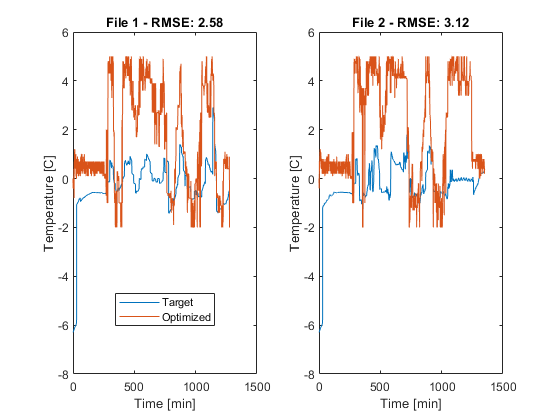

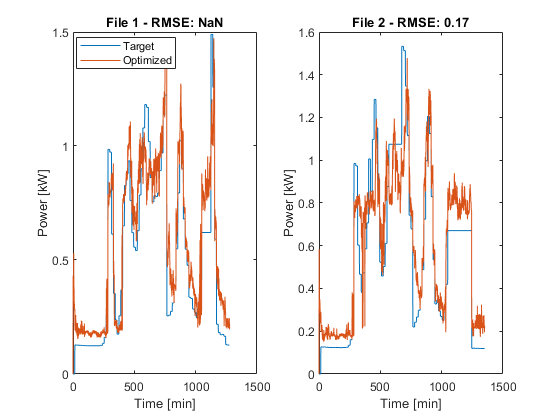

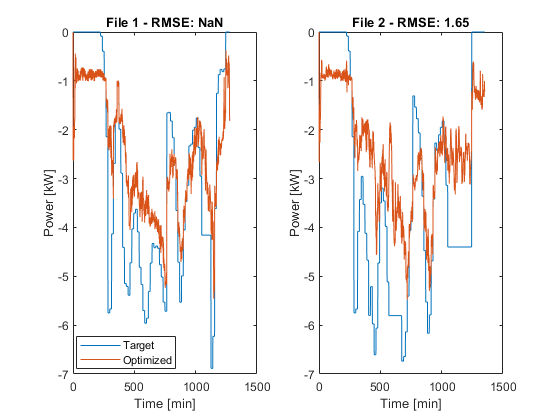

Average computation time per iteration: 0.097 seconds


Average computation time per iteration: 0.094 seconds


% Initialize figures to hold all subplots
fig_error = figure;
fig_power = figure;
fig_sen = figure;

% Subplot grid
numFiles = length(fileData);
numCols = ceil(sqrt(numFiles)); 
numRows = ceil(numFiles / numCols);

% Loop through all data files
for i = 1:length(fileData)
    
    % Load data
    time_step = fileData(i).time_step;
    error = fileData(i).error;
    acc_error = fileData(i).acc_error;
    inlet_water_temp = fileData(i).inlet_water_temp;
    return_air_temp = fileData(i).return_air_temp;
    return_air_hr = fileData(i).return_air_hr;
    wshp_power = fileData(i).wshp_power;
    sen_load = fileData(i).sen_load;
    lat_load = fileData(i).lat_load;
    wshp_power_mpc = fileData(i).wshp_power_mpc;
    sen_load_mpc = fileData(i).sen_load_mpc;
    
    % Search for an optimized error at each timestep
    for j = 2:length(time_step)

        % Start the timer
        tic;
        
        % Initialize an array for error search
        x1 = [-2:0.1:5]';
        
        % Accumulated error array
        acc_error_p = acc_error(j-1);
        x2 = max(min(acc_error_p + x1*12, 3000), 0);
        
        % History of other features
        x3 = inlet_water_temp(j-1) + zeros(length(x1),1);
        x4 = return_air_temp(j-1) + zeros(length(x1),1);
        x5 = return_air_hr(j-1) + zeros(length(x1),1);
        
        % Form features
        X = [x1,x2,x3,x4,x5];
        
        % Predict power
        power_pred = predict(power_model, X);
        sen_load_pred = predict(sen_load_model,X);
        
        % Target power
        power_target = wshp_power_mpc(j);
        sen_load_target = sen_load_mpc(j);
        
        % Calculate the Euclidean distance for each prediction from the target values
        distances = sqrt(10*(power_pred - power_target).^2 + (sen_load_pred - sen_load_target).^2);
        
        % Find the location of the closest match across all parameters
        [~, best_match_index] = min(distances);
        
        % Return the power and error at that location
        error_found(j,1) = x1(best_match_index);
        power_found(j,1) = power_pred(best_match_index);
        sen_load_found(j,1) = sen_load_pred(best_match_index);
        
        % Stop the timer
        computation_time(j) = toc;
        
    end

    % Display the average computation time
    fprintf('Average computation time per iteration: %.3f seconds\n', mean(computation_time));

    % Error figure
    figure(fig_error);
    
    % Calculate RMSE
    rmse = sqrt(mean((error - error_found).^2));   
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
    plot(time_step, error); % Actual in blue
    hold on;
    plot(time_step, error_found); % Predicted in red
    hold off;
    
    title(sprintf('File %d - RMSE: %.2f', i, rmse));
    xlabel('Time [min]');
    ylabel('Error');
    ylabel('Temperature [C]');
    if i == 1
        legend({'Target', 'Optimized'}, 'Location', 'best');
    end
    
    % Power figure
    figure(fig_power);
    
    % Calculate RMSE
    rmse = sqrt(mean((wshp_power_mpc - power_found).^2));   
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
    plot(time_step, wshp_power_mpc);
    hold on;
    plot(time_step, power_found); 
    hold off;
    
    title(sprintf('File %d - RMSE: %.2f', i, rmse));
    xlabel('Time [min]');
    ylabel('WSHP Power');
    ylabel('Power [kW]');
    if i == 1
        legend({'Target', 'Optimized'}, 'Location', 'best');
    end 
    
    % Sensible load figure
    figure(fig_sen);
    
    % Calculate RMSE
    rmse = sqrt(mean((sen_load_mpc - sen_load_found).^2));   
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
    plot(time_step, sen_load_mpc);
    hold on;
    plot(time_step, sen_load_found); 
    hold off;
    
    title(sprintf('File %d - RMSE: %.2f', i, rmse));
    xlabel('Time [min]');
    ylabel('Sensible Load');
    ylabel('Power [kW]');
    if i == 1
        legend({'Target', 'Optimized'}, 'Location', 'best');
    end  

end

## 🔁 Performance on speed matching

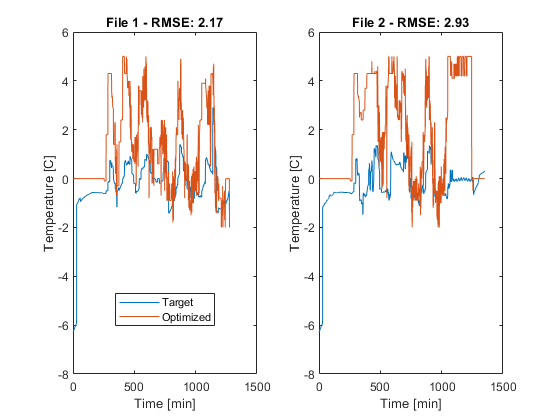

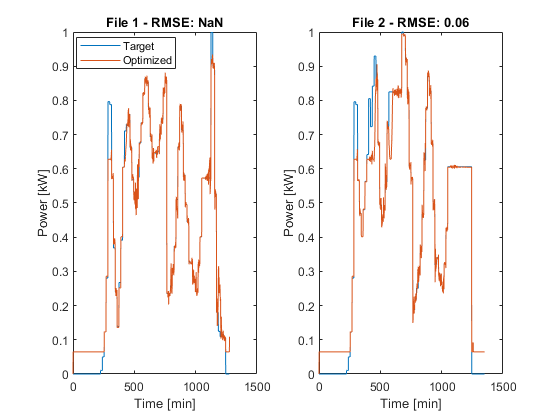

Average computation time per iteration: 0.117 seconds


Average computation time per iteration: 0.124 seconds


% Initialize figures to hold all subplots
fig_error = figure;
fig_comp_spd = figure;

% Subplot grid
numFiles = length(fileData);
numCols = ceil(sqrt(numFiles)); 
numRows = ceil(numFiles / numCols);

% Loop through all data files
for i = 1:length(fileData)
    
    % Load data
    time_step = fileData(i).time_step;
    error = fileData(i).error;
    acc_error = fileData(i).acc_error;
    inlet_water_temp = fileData(i).inlet_water_temp;
    return_air_temp = fileData(i).return_air_temp;
    return_air_hr = fileData(i).return_air_hr;
    wshp_power = fileData(i).wshp_power;
    sen_load = fileData(i).sen_load;
    lat_load = fileData(i).lat_load;
    wshp_power_mpc = fileData(i).wshp_power_mpc;
    sen_load_mpc = fileData(i).sen_load_mpc;
    comp_spd = fileData(i).comp_spd;
    comp_spd_mpc = fileData(i).comp_spd_mpc;
    
    % Search for an optimized error at each timestep
    for j = 2:length(time_step)

        % Start the timer
        tic;
        
        % Initialize an array for error search
        x1 = [-2:0.1:5]';
        
        % Accumulated error array
        acc_error_p = acc_error(j-1);
        x2 = max(min(acc_error_p + x1*12, 3000), 0);
        
        % Form features
        X = [x1,x2];
        
        % Predict power
        comp_spd_pred = predict(comp_spd_model, X);
        
        % Target power
        comp_spd_target = comp_spd_mpc(j);
        
        % Calculate the Euclidean distance for each prediction from the target values
        distances = sqrt((comp_spd_pred - comp_spd_target).^2 );
        
        % Find the location of the closest match across all parameters
        [~, best_match_index] = min(distances);
        
        % Return the power and error at that location
        error_found(j,1) = x1(best_match_index);
        comp_spd_found(j,1) = comp_spd_pred(best_match_index);
        
        % Stop the timer
        computation_time(j) = toc;
        
    end

    % Display the average computation time
    fprintf('Average computation time per iteration: %.3f seconds\n', mean(computation_time));

    % Error figure
    figure(fig_error);
    
    % Calculate RMSE
    rmse = sqrt(mean((error - error_found).^2));   
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
    plot(time_step, error); % Actual in blue
    hold on;
    plot(time_step, error_found); % Predicted in red
    hold off;
    
    title(sprintf('File %d - RMSE: %.2f', i, rmse));
    xlabel('Time [min]');
    ylabel('Error');
    ylabel('Temperature [C]');
    if i == 1
        legend({'Target', 'Optimized'}, 'Location', 'best');
    end
    
    % Power figure
    figure(fig_comp_spd);
    
    % Calculate RMSE
    rmse = sqrt(mean((comp_spd_mpc - comp_spd_found).^2));   
    
    % Plot the actual vs predicted values in a subplot
    subplot(numRows, numCols, i);
    plot(time_step, comp_spd_mpc);
    hold on;
    plot(time_step, comp_spd_found); 
    hold off;
    
    title(sprintf('File %d - RMSE: %.2f', i, rmse));
    xlabel('Time [min]');
    ylabel('WSHP Power');
    ylabel('Power [kW]');
    if i == 1
        legend({'Target', 'Optimized'}, 'Location', 'best');
    end

end